% 码长
n = 7;

% 信息位长
k = 4;

% 传输比特块数
M = 10000;

% 生成矩阵
Q = [1 1 1; 1 1 0; 1 0 1; 0 1 1];
G = [eye(k) Q];

% 监督矩阵
H = [Q;eye(3)]';

% 随机生成M个需要传输的比特块
x_data = randi([0 1], M, k);            %包含M个bit块，4M个bit
% 将每个比特块编码成（7，4）汉明码
x_code = mod(x_data*G , 2); %进行编码


% 经过误符号率为p的BSC信道
p_array=logspace(-3,log10(0.2),100);
%p_array=[0.001 0.005 0.01 0.05 0.1 0.2]
D=length(p_array);
BlockErrorRate_uncode=zeros(1,D);
BitErrorRate_uncode=zeros(1,D);
BlockErrorRate_code = zeros(1,D);
BitErrorRate_code = zeros(1,D);


for ord=1:D

p = p_array(ord);
noise = rand(M, n) < p;
y = mod(x_code + noise, 2);             %这里是叠加上B后的总结果，是01bit序列
 
% 利用监督矩阵计算校正子
syndrome = mod(y*H',2);
%syndrome = y*H';


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 比较校正子和监督矩阵，找出错误位置
error_positions = zeros(M,1);
for i = 1:M
    if ismember(H',syndrome(i,:),'rows') == zeros(n,1)                      %ismember - 判断数组元素是否为集数组成员(row为行)
        error_positions(i,1) = 0; 
    else
        error_positions(i,1) = find(ismember(H',syndrome(i,:),'rows'));     %find - 查找非零元素的索引和值
    end
end

% 进行纠错
y_decode = y;
for i = 1:M
    if error_positions(i,1) ~= 0
        y_decode(i, error_positions(i,1)) = ~y_decode(i, error_positions(i,1)); %简单取反
    end
end
% 去掉监督位
y_decode = y_decode(:,1:k);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 计算无信道编码时的误块率和误比特率
result_uncode = mod(x_data+y(:,1:k),2);%将x与y相加，若完全相同则全0
BlockErrorRate_uncode(ord) = sum(~ismember(result_uncode,zeros(1,k),'rows'))/M;%误块率
BitErrorRate_uncode(ord) = sum(result_uncode,'all')/(M*k);%误比特率

% 计算有信道编码时的误块率和误比特率
result_code = mod(x_data+y_decode(:,1:k),2);
BlockErrorRate_code(ord) = sum(~ismember(result_code,zeros(1,k),'rows'))/M;
BitErrorRate_code(ord) = sum(result_code,'all')/(M*k);


end


### 绘图

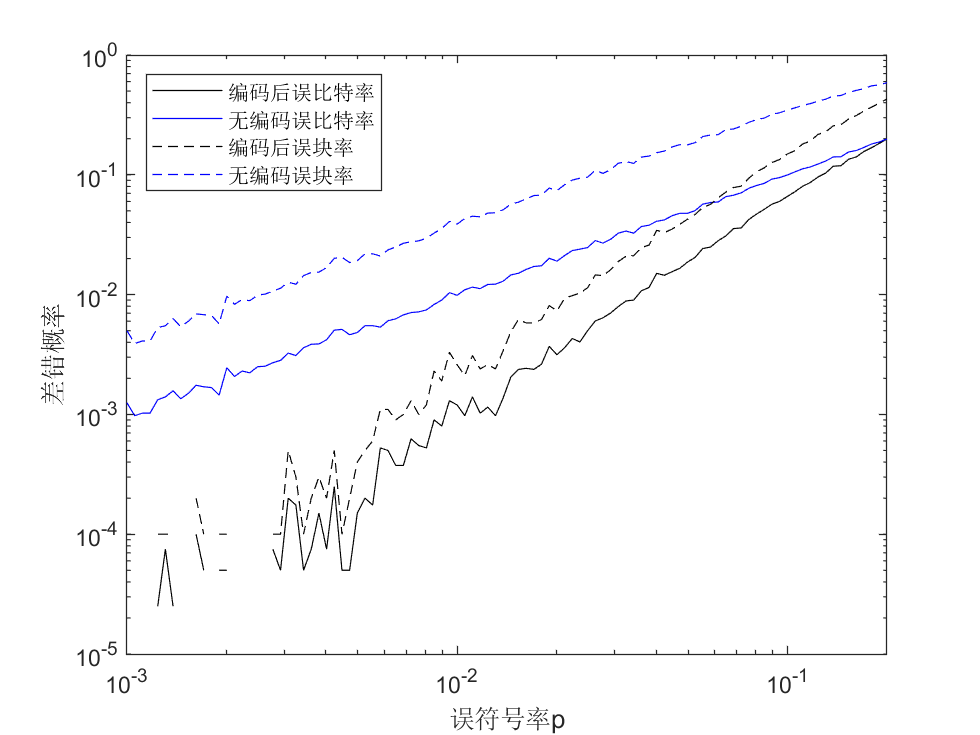

loglog(p_array,BitErrorRate_code,'-k',p_array,BitErrorRate_uncode,'-b', ...
    p_array,BlockErrorRate_code,'--k',p_array,BlockErrorRate_uncode,'--b');
legend('编码后误比特率','无编码误比特率','编码后误块率','无编码误块率','Location','northwest');
xlabel('误符号率p');
ylabel('差错概率');

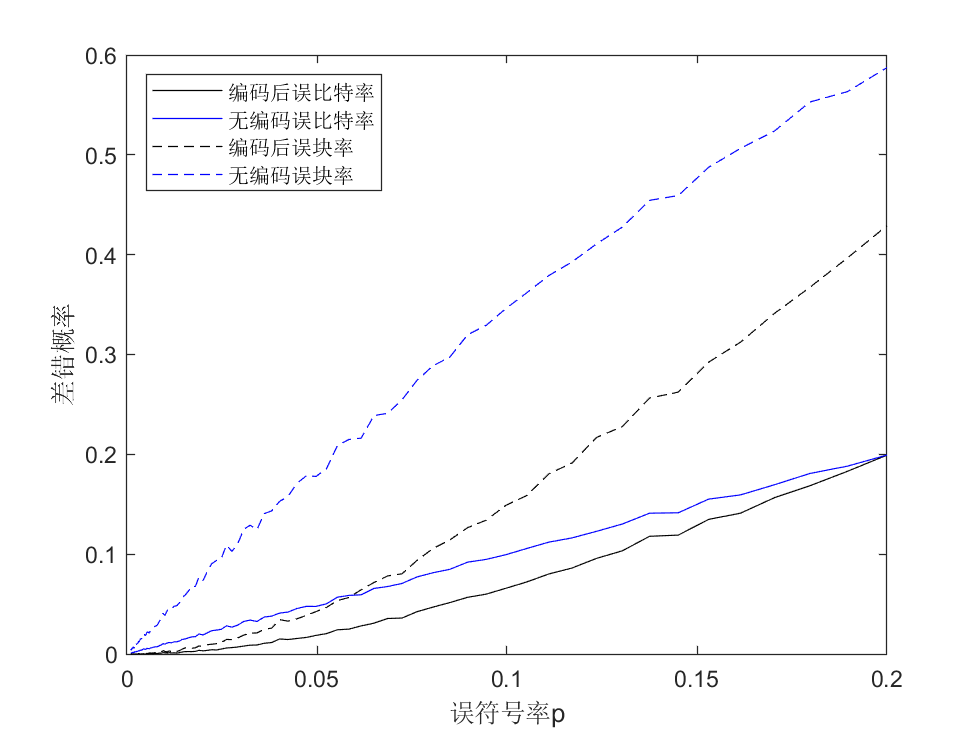



figure;
plot(p_array,BitErrorRate_code,'-k',p_array,BitErrorRate_uncode,'-b', ...
    p_array,BlockErrorRate_code,'--k',p_array,BlockErrorRate_uncode,'--b');
legend('编码后误比特率','无编码误比特率','编码后误块率','无编码误块率','Location','northwest');
xlabel('误符号率p');
ylabel('差错概率');